%Generacja systemu
r_min=-5;
r_max=5;
r=(r_min-r_max).*rand()+r_max;
b0=2*r;
r=(r_min-r_max).*rand()+r_max;
a0=2*r;
r=(r_min-r_max).*rand()+r_max;
a1=2*r;
r=(r_min-r_max).*rand()+r_max;
a2=2*r;
r=(r_min-r_max).*rand()+r_max;
a3=2*r;

a3=1;
a2=6;
a1=2;
a0=1;
b0=1;

L=[b0];
M=[a3 a2 a1 a0];
sys=tf(L,M)

sys =
 
            1
  ---------------------
  s^3 + 6 s^2 + 2 s + 1
 
Continuous-time transfer function.



[A, B, C, D]=tf2ss(L,M)

A =     -6    -2    -1
     1     0     0
     0     1     0


B =      1
     0
     0


C =      0     0     1


D = 0

% norm(A,"fro")
% step(sys,0:0.1:30);

%Toeplitz
H1=1/a3*[a1 a2 a3 0; a2 a3 0 0; a3 0 0 0]

H1 =      2     6     1     0
     6     1     0     0
     1     0     0     0


H2=1/a3*[b0 0 0 0; 0 0 0 0; 0 0 0 0]

H2 =      1     0     0     0
     0     0     0     0
     0     0     0     0


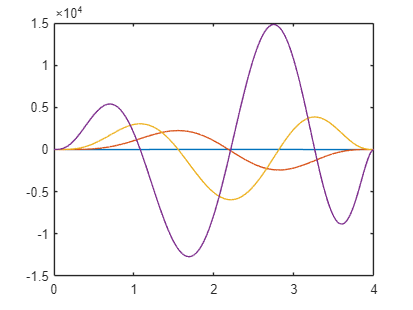

%funkcja phi /znormalizować
h=4;
step_size=0.001;
t=0:step_size:h;
N=6;
M=5;
% global phi phi_1 phi_2;
phi=(t.^N).*((h-t).^M);
phi=phi/max(abs(phi));
% phi_1=diff(phi)/step_size;
phi_1=(N*t.^(N-1)).*((h-t).^M)-(M*t.^N).*(h-t).^(M-1);
phi_1=phi_1/max(abs(phi));
% phi_2=diff(phi_1)/step_size;
phi_2=(M*t.^N).*((h-t).^(M-2)).*(M-1)-(2*M*N*t.^(N-1)).*((h-t).^(M-1))+(N*t.^(N-2).*((h-t).^M)*(N-1));
phi_2=phi_2/max(abs(phi));
phi_3=3*M*N*t.^(N - 1).*(h - t).^(M - 2).*(M - 1) - M*t.^N.*(h - t).^(M - 3).*(M - 1).*(M - 2) - 3*M*N*t.^(N - 2).*(h - t).^(M - 1).*(N - 1) + N*t.^(N - 3).*(h - t).^M.*(N - 1).*(N - 2); 
phi_3=phi_3/max(abs(phi));
plot(t,phi,t,phi_1,t,phi_2,t,phi_3)

trapz(t,phi,2)

ans = 1.4119

trapz(t,phi_1,2)

ans = -2.5173e-13

trapz(t,phi_2,2)

ans = 6.8274e-10

trapz(t,phi_3,2)

ans = 7.1671e-09

conv_size=length(phi);
T_iD=8/step_size;

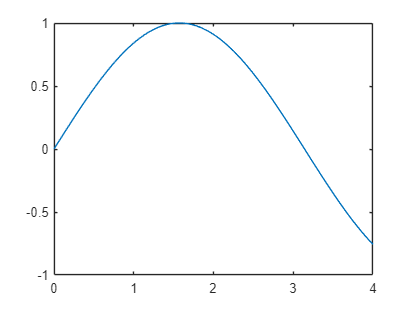

plot(t,sin(t))

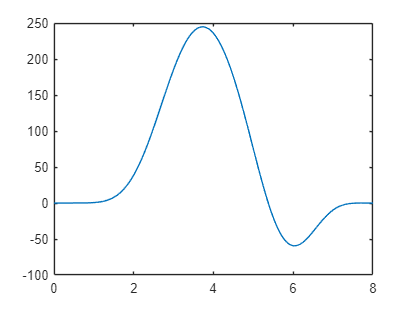

% plot(t,cumtrapz(t,sin(t)))
vec=0:step_size:(length(conv(sin(t),phi))-1)*step_size;
conv_plot=conv(sin(t),phi);
plot(vec,conv_plot)

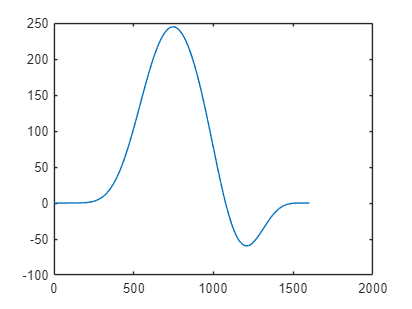

clear splot_1 splot_2
sinus=sin(t);
for j=1:length(sinus)+length(phi)-2
    clear splot_1
    if j<=length(sinus)        
        splot_1=sinus(1:j).*fliplr(phi(1:j));        
    else
        splot_1=sinus((j-length(sinus)):end).*fliplr(phi((j-length(sinus)):end));
    end
    splot_2(j)=trapz([0:step_size:(length(splot_1)-1)*step_size],splot_1,2);
end
SINUS=fft([sinus zeros(1,length(phi)-1)]);
PHI=fft([phi zeros(1,length(sinus)-1)]);
plot(ifft(SINUS.*PHI))

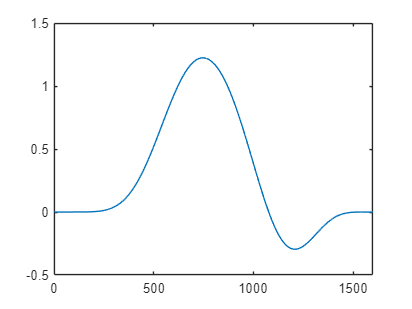

% plot(splot_1)
% xlim([0 400])
plot(splot_2)

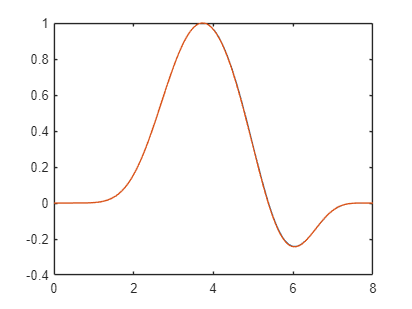

plot(vec(1:end-1),splot_2/max(splot_2),vec,conv_plot/max(conv_plot))

% xlim([0 400])
% plot(vec,conv(sin(t),phi_1))
% plot(cumtrapz(vec,conv(sin(t),phi),2))
% plot(vec,cumtrapz(vec,conv(sin(t),phi_1),2)*4.25,vec,conv(sin(t),phi))

%optymalna identyfikacja


%Regulator
K=[0.1 0.1 0.1];
Ac=A-B*K;
Q=[1 0 0;
   0 1 0;
   0 0 1];
[K, S, poles]=lqr(A,B,Q,[0.01])

K =     7.0237   16.8089    9.0499


S =     0.0702    0.1681    0.0905
    0.1681    2.2391    1.2489
    0.0905    1.2489    1.8703


poles =   -0.7824 + 0.5146i
  -0.7824 - 0.5146i
 -11.4588 + 0.0000i


K=K/20000

K = 	1.0e+-3 *

    0.3512    0.8404    0.4525


syms t N h M
phi_anal(t) = (t^N)*((h-t)^M);
phi_anal1(t)=diff(phi_anal,t)
phi_anal2(t)=diff(phi_anal1,t)
phi_anal3(t)=diff(phi_anal2,t)